# **使用 streamline 绘制电力线**

**       使用streamline函数当然也可以绘制电场强度。此时，需要建立分布在二维或者三维空间中的电场强度。以点电荷对为例进行绘制。对于初始电力线位置的考虑，因电力线起于正电荷，止于负电荷，当起始点距电荷很近时，认为各起始点绕电荷均匀分布。因此，取围绕点电荷的一个小圆为参考，以某个固定角度为间隔，将圆周均分，则可以设定电力线在正、负电荷周围的起点坐标。**

- **生成网格**

figure
x=-4:0.02:4;y=x;                     	%生成一系列坐标x,y
[X,Y]=meshgrid(x,y);                  	%生成网格数据

- **计算场点距离、电势、电场强度**

R1=sqrt((X+1).^2+Y.^2);                	%场点距离左侧电荷的距离
R2=sqrt((X-1).^2+Y.^2);                 %场点距离右侧电荷的距离
Q=3;
phi=1./R1+Q./R2;                        %计算电势
[Ex,Ey]=gradient(-phi);                 %取梯度计算电场

- **计算电荷起点坐标**

hold on                             	%叠加绘图模式
r0=0.1;                                	%电场线起点所在圆半径
th=20:20:360-20;                      	%以20度为间隔，均分圆周
th=th*pi/180;                         	%转换角度为弧度
xl=r0*cos(th)-1;                       	%左侧电荷起点横坐标
yl=r0*sin(th);                         	%左侧电荷起点纵坐标

- **使用 streamline 绘制电力线**

**        需要指出的是，若电力线分布在正电荷周围，从正电荷发出，则绘制流线时取场分布为[Ex,Ey]；若电力线分布在负电荷周围，终止于负电荷，则绘制流线时取[-Ex,-Ey]。**

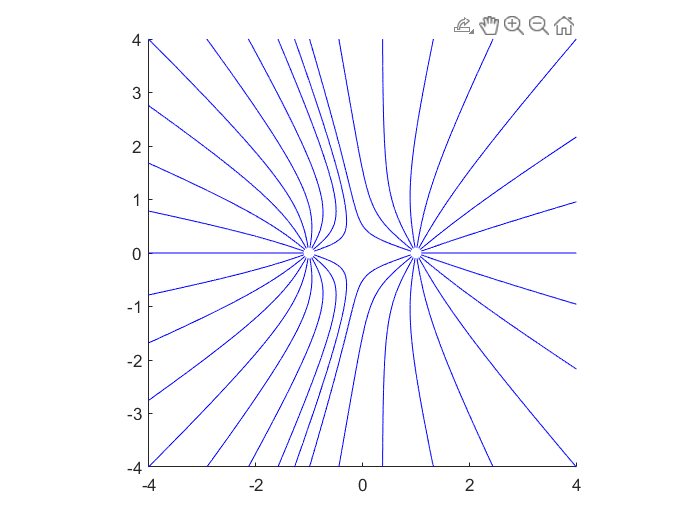

h=streamline(X,Y,Ex,Ey,xl,yl);          %绘制左侧电荷对应的流线，即为电场线
xr=-xl;                              	%右侧电荷对应的起始点横坐标          
yr=yl;                               	%右侧电荷对应的起始点纵坐标 
if Q>0
    h=streamline(X,Y,Ex,Ey,xr,yr);          %绘制右侧电荷对应的流线
elseif Q<0
    h=streamline(X,Y,-Ex,-Ey,xr,yr);   	    %绘制右侧电荷对应的流线
else
    disp('错误的Q值');
end
axis image;                           	%等比例绘制图像
axis([-4 4 -4 4]);
set(gcf,'Visible','on');   	    %强制图片弹出显示